clear;
close all;
clc;
initime = clock;
addpath('C:\zheng\mywork\attentioncolumn\matlab\funcs');
load C:\zheng\mywork\attentioncolumn\matlab\lateral\all_0_0.5_0_0.05_Iattn_0.02.mat
cd C:\zheng\mywork\attentioncolumn\paper\figure3

Delta_e_start = 0; % cannot equal to 0
Delta_e_end = 0.5; % can equal to 0.5

Delta_i_start = 0; % cannot equal to 0
Delta_i_end = 0.05; % can equal to 0.05
steps = 200;

Iattn = 0.02;

n = 1:200;
Delta_e = Delta_e_start+ n*(Delta_e_end/steps);
Delta_i = Delta_i_start + n*(Delta_i_end/steps);
sz = 4;
steps = size(orderSheet,1);

## Parameter plane (Iattn=0.02)

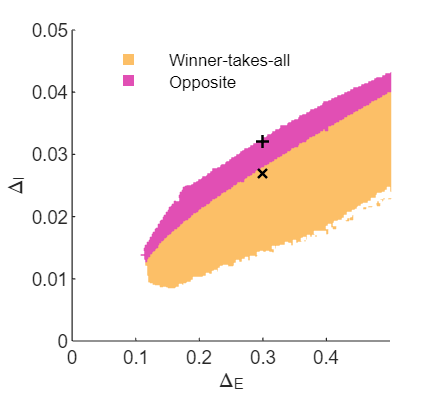

level = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if levelSheet(i,j,1) < levelSheet(i,j,2) && levelSheet(i,j,1) < levelSheet(i,j,5)
            level(i,j) = 1;
        end
    end
end

% lateral and order agree
roi = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if sum(lateralSheet(i,j,:)~=1) == 0 && level(i,j) == 1 && orderSheet(i,j) == 1
            roi(i,j) = 1;
        end
    end
end

roi = roi == 1;

figure();
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#FCBF67"); % yellow
    hold on
end

% lateral disagree, order agree
roi = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if lateralSheet(i,j,4)==0 && lateralSheet(i,j,5)==0 && level(i,j) == 1 && orderSheet(i,j) == 1
            roi(i,j) = 1;
        end
    end
end


roi = roi == 1;

% plot
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s2 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#E14FB4"); % magenta
end

% paint white
% gamma/+beta but order agree
roi = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if sum(betaSheet(i,j,:)>0)>0
            roi(i,j) = 1;
        end
    end
end

roi = roi == 1;
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s3 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#FFFFFF"); % white
    hold on
end

scatter(0.3, 0.027,30, "x","MarkerEdgeColor","k","LineWidth",1);
scatter(0.3, 0.032,30, "+","MarkerEdgeColor","k","LineWidth",1);
xlabel("\Delta_{E}");
ylabel("\Delta_{I}");
axis([Delta_e_start Delta_e_end Delta_i_start Delta_i_end]);
legend([s1 s2],["Winner-takes-all", "Opposite"],"Location","northwest");
legend boxoff;

x0 = 0; y0 = 0; width = 6.5; height = 6;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print('paraPlane02', '-dpng', '-r600');
print('paraPlane02', '-depsc', '-r600');

## Iattn = 0.03

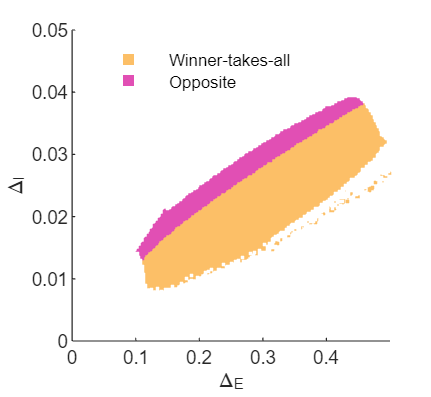

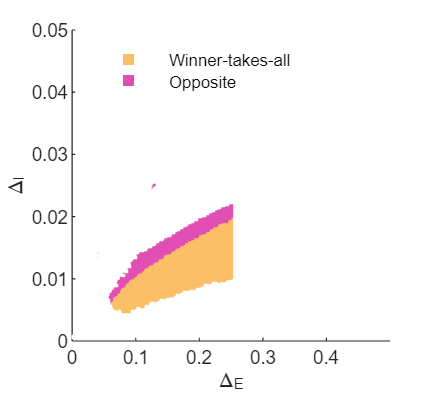

load C:\zheng\mywork\attentioncolumn\matlab\lateral\all_0_0.5_0_0.05_Iattn_0.03.mat
cd C:\zheng\mywork\attentioncolumn\paper\figure3

level = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if levelSheet(i,j,1) < levelSheet(i,j,2) && levelSheet(i,j,1) < levelSheet(i,j,5)
            level(i,j) = 1;
        end
    end
end

% lateral and order agree
roi = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if sum(lateralSheet(i,j,:)~=1) == 0 && level(i,j) == 1 && orderSheet(i,j) == 1
            roi(i,j) = 1;
        end
    end
end

roi = roi == 1;

figure();
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#FCBF67"); % yellow
    hold on
end

% lateral disagree, order agree
roi = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if lateralSheet(i,j,4)==0 && lateralSheet(i,j,5)==0 && level(i,j) == 1 && orderSheet(i,j) == 1
            roi(i,j) = 1;
        end
    end
end


roi = roi == 1;

% plot
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s2 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#E14FB4"); % magenta
end

% paint white
% gamma/+beta but order agree
roi = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if sum(betaSheet(i,j,:)>0)>0
            roi(i,j) = 1;
        end
    end
end

roi = roi == 1;
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s3 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#FFFFFF"); % white
    hold on
end

xlabel("\Delta_{E}");
ylabel("\Delta_{I}");
axis([Delta_e_start Delta_e_end Delta_i_start Delta_i_end]);
legend([s1 s2],["Winner-takes-all", "Opposite"],"Location","northwest");
legend boxoff;

x0 = 0; y0 = 0; width = 6.5; height = 6;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print('paraPlane03', '-dpng', '-r600');
print('paraPlane03', '-depsc', '-r600');

## Iattn = 0.01

load C:\zheng\mywork\attentioncolumn\matlab\lateral\all_0_0.5_0_0.05_Iattn_0.01.mat
cd C:\zheng\mywork\attentioncolumn\paper\figure3

level = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if levelSheet(i,j,1) < levelSheet(i,j,2) && levelSheet(i,j,1) < levelSheet(i,j,5)
            level(i,j) = 1;
        end
    end
end

% lateral and order agree
roi = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if sum(lateralSheet(i,j,:)~=1) == 0 && level(i,j) == 1 && orderSheet(i,j) == 1
            roi(i,j) = 1;
        end
    end
end

roi = roi == 1;

figure();
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#FCBF67"); % yellow
    hold on
end

% lateral disagree, order agree
roi = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if lateralSheet(i,j,4)==0 && lateralSheet(i,j,5)==0 && level(i,j) == 1 && orderSheet(i,j) == 1
            roi(i,j) = 1;
        end
    end
end


roi = roi == 1;

% plot
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s2 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#E14FB4"); % magenta
end

% paint white
% gamma/+beta but order agree
roi = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if sum(betaSheet(i,j,:)>0)>0
            roi(i,j) = 1;
        end
    end
end

roi = roi == 1;
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s3 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#FFFFFF"); % white
    hold on
end

xlabel("\Delta_{E}");
ylabel("\Delta_{I}");
axis([Delta_e_start Delta_e_end Delta_i_start Delta_i_end]);
legend([s1 s2],["Winner-takes-all", "Opposite"],"Location","northwest");
legend boxoff;

x0 = 0; y0 = 0; width = 6.5; height = 6;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print('paraPlane03', '-dpng', '-r600');
print('paraPlane03', '-depsc', '-r600');


## bar chart

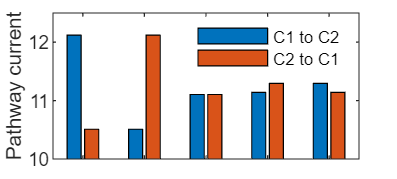

cd C:\zheng\mywork\attentioncolumn\paper\figure3
addpath('C:\zheng\mywork\attentioncolumn\matlab\funcs');

Delta_e = 0.3;
Delta_i = 0.032;
Iattn = 0.02;
alltime = 4000;
prd = 100000;
[r,v,g] = once(Delta_e, Delta_i, Iattn, alltime);
PET = getPET(v(:,end-prd:end,:),g(:,:,end-prd:end,:)); 
oneTwo = squeeze(PET(10,1,:));
twoOne = squeeze(PET(2,9,:));

figure();
b = bar([oneTwo,twoOne]);
ylim([10 12.5]);
set(gca,'XTickLabels',[]);
ylabel("Pathway current");
legend("C1 to C2","C2 to C1",'Location','northeast');
legend boxoff;

x0 = 0; y0 = 0; width = 6; height = 2.7;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print('barUp', '-dpng', '-r600');
print('barUp', '-depsc', '-r600');

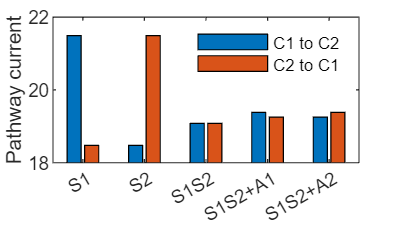



Delta_e = 0.3;
Delta_i = 0.027;
Iattn = 0.02;
alltime = 4000;
prd = 100000;
[r,v,g] = once(Delta_e, Delta_i, Iattn, alltime);
PET = getPET(v(:,end-prd:end,:),g(:,:,end-prd:end,:)); 
oneTwo = squeeze(PET(10,1,:));
twoOne = squeeze(PET(2,9,:));

figure();
b = bar([oneTwo,twoOne]);
ylim([18 22]);
set(gca,'XTickLabels',[]);
xticklabels(["S1", "S2", "S1S2", "S1S2+A1", "S1S2+A2"]);
ylabel("Pathway current");
legend("C1 to C2","C2 to C1",'Location','northeast');
legend boxoff;

x0 = 0; y0 = 0; width = 6; height = 3.4;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print('barDown', '-dpng', '-r600');
print('barDown', '-depsc', '-r600');

## change lateral: up

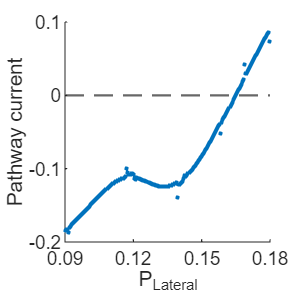

load C:\zheng\mywork\attentioncolumn\matlab\lateral\finalR_cLateral_0.09_0.18_DeltaE_0.3_DeltaI_0.032_Iattn_0.02_steps_201.mat
cd C:\zheng\mywork\attentioncolumn\paper\figure3

lateral_start = 0.09;
lateral_end = 0.18; 

steps = 201;

sz = 3;
x = linspace(lateral_start,lateral_end,size(PETAsheet,1));
y1 = PETAsheet(:,10,1,4);
y2 = PETAsheet(:,2,9,4);

% % find zero point
% z = y2 - y1; 
% [~, idxP] = min(z(z>0));
% x0 = (x(idxP) + x(idxP+1))/2;

figure();
s1 = scatter(x,y1-y2,sz,'filled','MarkerFaceColor',"#0072BD");
hold on;
yline(0,"--","LineWidth",1);

xlim([0.09 0.18]);
ylim([-0.2 0.1]);
% legend([s1 s2],["C1 to C2","C2 to C1"],"Location","Southeast");
xlabel("P_{Lateral}");
ylabel("Pathway current");
xticks([0.09 0.12 0.15 0.18]);
x0 = 0; y0 = 0; width = 4.5; height = 4.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print('cLateralUp', '-dpng', '-r600');
print('cLateralUp', '-depsc', '-r600');

## change lateral: down

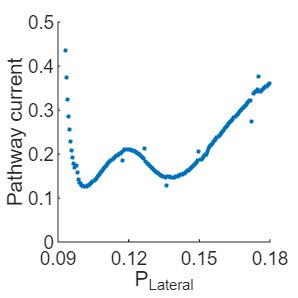

load C:\zheng\mywork\attentioncolumn\matlab\lateral\finalR_cLateral_0.09_0.18_DeltaE_0.3_DeltaI_0.027_Iattn_0.02_steps_201.mat
cd C:\zheng\mywork\attentioncolumn\paper\figure3

lateral_start = 0.09;
lateral_end = 0.18; 

steps = 201;

sz = 3;
x = linspace(lateral_start,lateral_end,size(PETAsheet,1));
y1 = PETAsheet(:,10,1,4);
y2 = PETAsheet(:,2,9,4);

% % find zero point
% z = y2 - y1; 
% [~, idxP] = min(z(z>0));
% x0 = (x(idxP) + x(idxP+1))/2;

figure();
s1 = scatter(x,y1-y2,sz,'filled','MarkerFaceColor',"#0072BD");
hold on;
% s2 = scatter(x,y2,sz,'filled','MarkerFaceColor',"#D95319");
% xline(x0,'LineWidth',1);
% yline(0,'LineWidth',1);

xlim([0.09 0.18]);
ylim([0 0.5]);
% legend([s1 s2],["C1 to C2","C2 to C1"],"Location","Southeast");
xlabel("P_{Lateral}");
ylabel("Pathway current");
xticks([0.09 0.12 0.15 0.18]);
x0 = 0; y0 = 0; width = 4.5; height = 4.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print('cLateralDown', '-dpng', '-r600');
print('cLateralDown', '-depsc', '-r600');

## try Iattn

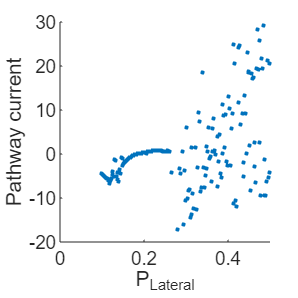

load C:\zheng\mywork\attentioncolumn\matlab\lateral\Iattn_cLateral_0.1_0.5_DeltaE_0.3_DeltaI_0.032_lateral_0.1_steps_201.mat
cd C:\zheng\mywork\attentioncolumn\paper\figure3

lateral_start = 0.1;
lateral_end = 0.5; 

steps = 201;

sz = 3;
x = linspace(lateral_start,lateral_end,size(PETAsheet,1));
y1 = PETAsheet(:,10,1,4);
y2 = PETAsheet(:,2,9,4);

% % find zero point
% z = y2 - y1; 
% [~, idxP] = min(z(z>0));
% x0 = (x(idxP) + x(idxP+1))/2;

figure();
s1 = scatter(x,y1-y2,sz,'filled','MarkerFaceColor',"#0072BD");
hold on;
% s2 = scatter(x,y2,sz,'filled','MarkerFaceColor',"#D95319");
% xline(x0,'LineWidth',1);
% yline(0,'LineWidth',1);

% xlim([0.001 0.1]);
% ylim([0 0.5]);
% legend([s1 s2],["C1 to C2","C2 to C1"],"Location","Southeast");
xlabel("P_{Lateral}");
ylabel("Pathway current");
x0 = 0; y0 = 0; width = 4.5; height = 4.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print('try', '-dpng', '-r600');
print('try', '-depsc', '-r600');